## VMD-HD

### Signal

filename = "vmd_hd_usecase2.mat";
hasMatFile = isfile(filename);
if (hasMatFile)
    load(filename);
end

if (~hasMatFile)
    fs = 1000;
    t = 0:1/fs:1;
    signal = cos(2*pi*2*t) + cos(2*pi*24*t) + cos(2*pi*100*t);
    raw = awgn(signal,5,0);
end

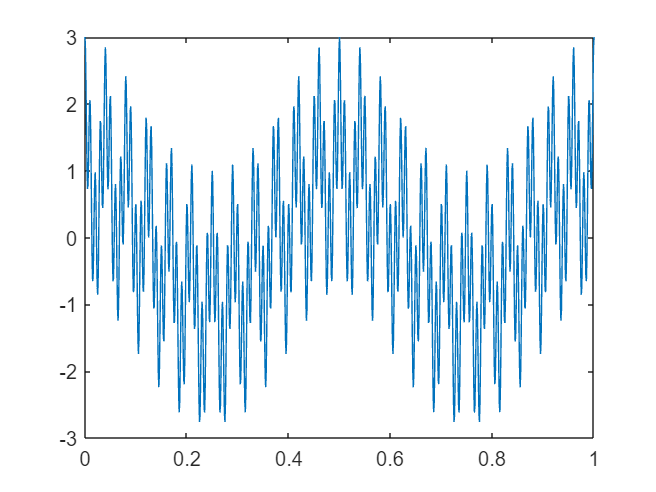

plot(t,signal);

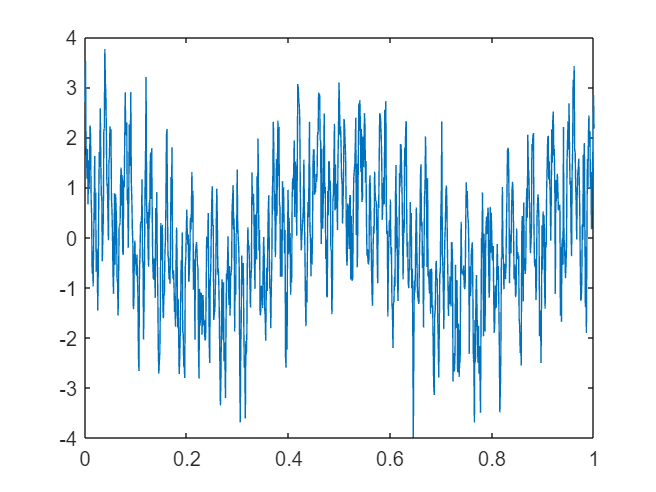

plot(t,raw);

if (~hasMatFile)
    % parameters:
    alpha = 5000;       % bandwidth constraint
    tau = 0.25;         % Lagrangian multipliers dual ascent time step
    K = 9;              % number of modes
    DC = 1;             % includes DC part (first mode at DC)
    
    init = 1;           % initialize omegas randomly, may need multiple runs!
    
    tol = K*10^-6;      % tolerance (for convergence)
    
    [u, u_hat, omega]=VMD(raw, alpha, tau, K, DC, init, tol);

end

if (~hasMatFile)
    save (filename)
end

### PDF

bincount = 50;
disp('paper func')

paper func


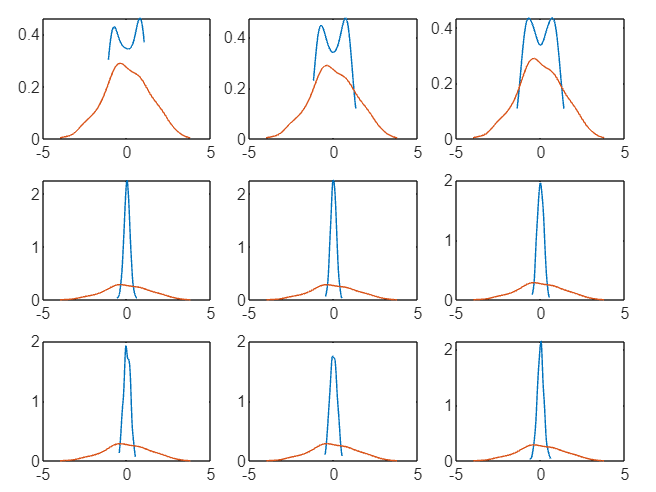

[pdfr,pdfs]=drawIMFhis(raw,u,bincount,K,'paper');

#### KLD

distKLD=[];
for i = 1:K
    p = pdfr(1,:);
    q = reshape(pdfs(i,1,:),1,[]);
    distKLD(i)= KLD(p,q);
end

#### KLDsym

distKLDsym=[];
for i = 1:K
    p = pdfr(1,:);
    q = reshape(pdfs(i,1,:),1,[]);
    distKLDsym(i)= (distKLD(i)+KLD(q,p))/2;
end

#### JSD

distJSD=[];
for i = 1:K
    p = pdfr(1,:);
    q = reshape(pdfs(i,1,:),1,[]);
    m = (p+q)/2;
    distJSD(i)= (KLD(p,m)+KLD(q,m))/2;
end

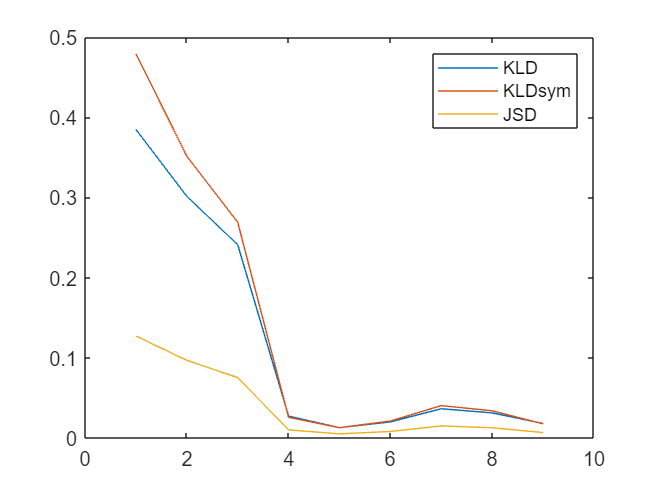

figure('Name','KLD');
plot(distKLD)
hold on
plot(distKLDsym)
hold on
plot(distJSD)
hold off
legend(["KLD","KLDsym","JSD"]);

#### HD

distHD=[];
for i = 1:K
    P = pdfr';
    Q = reshape(pdfs(i,:,:),2,[])';
    distHD(i)= hausdorffDist(P,Q);
end

#### l2-norm

distl2=[];
for i = 1:K
    P = pdfr';
    Q = reshape(pdfs(i,:,:),2,[])';
    distl2(i)= l2(P,Q);
end

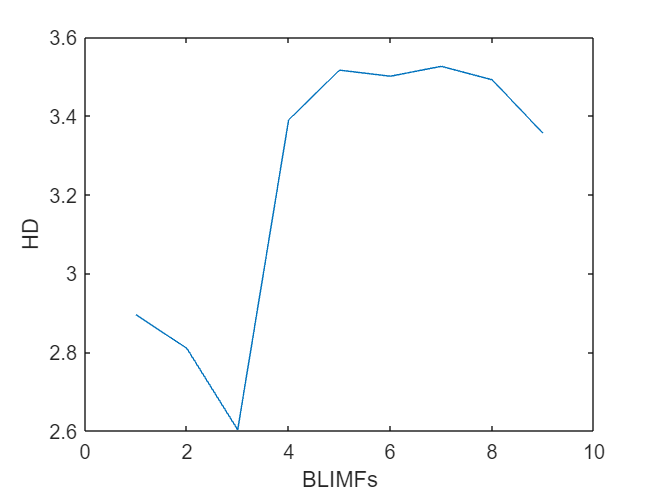

figure('Name','HD');
plot(distHD)
xlabel('BLIMFs')
ylabel('HD')

% hold on
% plot(distl2)
% hold off
% legend(["HD","l2norm"]);

## Maximum slope

disp('by l2');

by l2


[theta,hdi] = max(abs(distl2(1:K-1)-distl2(2:K)))

theta = 4.8013

hdi = 3

disp('by HD');

by HD


[theta,hdi] = max(abs(distHD(1:K-1)-distHD(2:K)))

theta = 0.7865

hdi = 3

## Reconstruct

reconstruct = [];
if (hdi==1)
    reconstruct = u(1,:);
else
    reconstruct = sum(u(1:hdi,:));
end

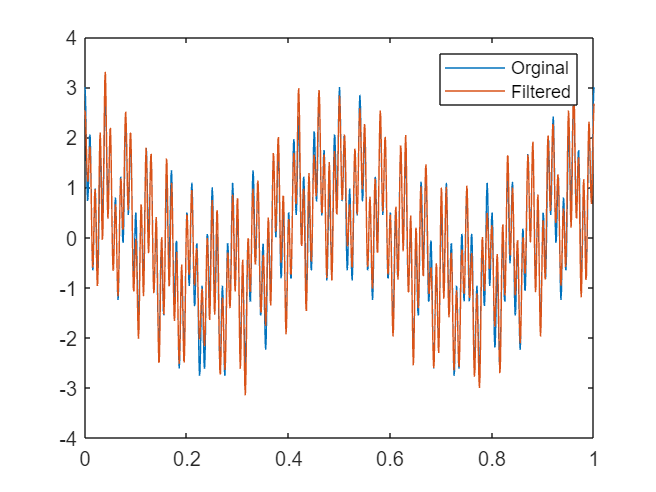

figure('Name','Compare');
plot(t,signal);
hold on
plot(t,reconstruct);
hold off
legend(["Orginal","Filtered"]);

### Spectrum

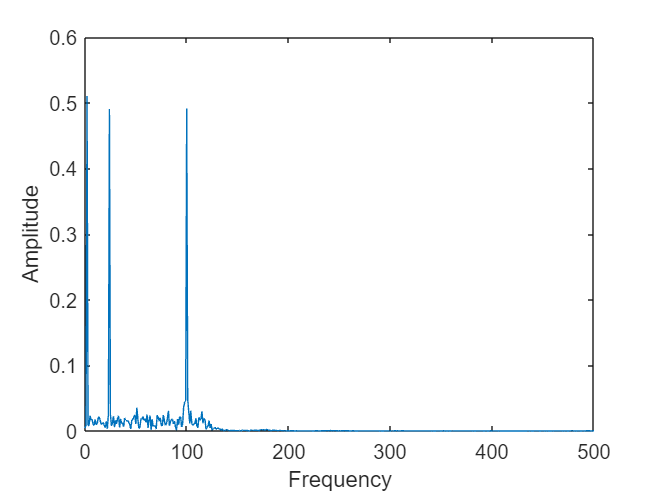

y = fft(reconstruct);
n = length(reconstruct);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y)/n;    % power of the DFT

figure('Name','Filtered fft');
plot(f,power)
xlabel('Frequency')
ylabel('Amplitude')
xlim([0 fs/2])

% set(gca, 'XScale', 'log')

function [ H ] = hausdorffDist(P,Q)
   D = pdist2(P,Q); % Distance calculation
   hab = max(min(D,[],2));% Directed from a to b
   hba = max(min(D));% Directed from b to a
   H = max([hab,hba]);
end

function d = l2(P,Q)
    D = pdist2(P,Q,"euclidean"); % Distance calculation
    sum = 0;
    for i=1:length(D)
        sum = sum+D(i,i)*D(i,i);
    end
    d = sqrt(sum);
end

function arrout = gethisarr(signal,bincount)
    % [N,edges] = histcounts(signal,bincount,'Normalization','pdf');
    % arrout(1,:) = N;
    % for e=1:(length(edges)-1)
    %     arrout(2,e) = (edges(e)+edges(e+1)) / 2;
    % end
    signal = reshape(signal,1,[]);
    % x = linspace(min(signal),max(signal),bincount);
    x = linspace(min(signal),max(signal),bincount);
    pd = fitdist(signal', 'kernel');
    y = pdf(pd,x);
    arrout = [y;x];
end

function [pdfr,pdfs]=drawIMFhis(raw,u,bincount,K,name)
    pdfr = gethisarr(raw,bincount);
    pdfs = zeros(K,2,bincount);
    for i = 1:K
        pdfs(i,:,:) = gethisarr(u(i,:),bincount);
    end
    figure('Name',"pdf "+name);
    tile = tiledlayout(K/3,3);
    tile.TileSpacing = 'compact';
    tile.Padding = 'compact';
    for i = 1:K
        nexttile;
        plot(reshape(pdfs(i,2,:),1,[]),reshape(pdfs(i,1,:),1,[]));
        hold on;
        plot(pdfr(2,:),pdfr(1,:));
        hold off;
    end
end
